% Obtendo u e v da solução original
% Para a nova solução ser válida, o resultado deve
% ser pelo menos próximo desse.
cavidade_2ordem

Passo: 1     Residuo:1.3434805785e-02    Residuo:1.0682979494e-02
Passo: 2     Residuo:1.2978833185e-02    Residuo:1.0267359722e-02
Passo: 3     Residuo:1.2542335310e-02    Residuo:9.8671570252e-03
Passo: 4     Residuo:1.2124407540e-02    Residuo:9.4819379046e-03
Passo: 5     Residuo:1.1724188540e-02    Residuo:9.1112665539e-03
Passo: 6     Residuo:1.1340858197e-02    Residuo:8.7547066883e-03
Passo: 7     Residuo:1.0973635654e-02    Residuo:8.4118231688e-03
Passo: 8     Residuo:1.0621777425e-02    Residuo:8.0821834397e-03
Passo: 9     Residuo:1.0284575607e-02    Residuo:7.7653587936e-03
Passo: 10     Residuo:9.9613561703e-03    Residuo:7.4609254786e-03
Passo: 11     Residuo:9.6514773211e-03    Residuo:7.1684656588e-03
Passo: 12     Residuo:9.3543279528e-03    Residuo:6.8875682436e-03
Passo: 13     Residuo:9.0693261613e-03    Residuo:6.6178295946e-03
Passo: 14     Residuo:8.7959178341e-03    Residuo:6.3588541227e-03
Passo: 15     Residuo:8.5339035367e-03    Residuo:6.1102547856e-03
Pass

u_original = u;
v_original = v;
% Clear em todas as variáveis exceto u e v originais
clearvars -except u_original v_original

[results, performanceInfo] = cavidade_2ordem_function(32, 32, 100000, 100, 0.001)

Passo: 1     Residuo:7.3995372158e-03    Residuo:1.0682979494e-02
Passo: 2     Residuo:7.0386416012e-03    Residuo:1.0223088608e-02
Passo: 3     Residuo:6.6933755367e-03    Residuo:9.7843844764e-03
Passo: 4     Residuo:6.3630809349e-03    Residuo:9.3658685331e-03
Passo: 5     Residuo:6.0471258315e-03    Residuo:8.9665895192e-03
Passo: 6     Residuo:5.7449035272e-03    Residuo:8.5856412267e-03
Passo: 7     Residuo:5.4558317384e-03    Residuo:8.2221603571e-03
Passo: 8     Residuo:5.1793517589e-03    Residuo:7.8753244874e-03
Passo: 9     Residuo:4.9149276340e-03    Residuo:7.5443501345e-03
Passo: 10     Residuo:4.6620453501e-03    Residuo:7.2284909156e-03
Passo: 11     Residuo:4.4202120394e-03    Residuo:6.9270357959e-03
Passo: 12     Residuo:4.1889552033e-03    Residuo:6.6393074211e-03
Passo: 13     Residuo:3.9678219532e-03    Residuo:6.3646605289e-03
Passo: 14     Residuo:3.7563782707e-03    Residuo:6.1024804361e-03
Passo: 15     Residuo:3.5542082877e-03    Residuo:5.8521815965e-03
Pass

results = struct with fields:
    x: [0 0.031250000000000 0.062500000000000 0.093750000000000 0.125000000000000 0.156250000000000 0.187500000000000 0.218750000000000 0.250000000000000 0.281250000000000 0.312500000000000 0.343750000000000 0.375000000000000 0.406250000000000 … ]
    y: [0 0.031250000000000 0.062500000000000 0.093750000000000 0.125000000000000 0.156250000000000 0.187500000000000 0.218750000000000 0.250000000000000 0.281250000000000 0.312500000000000 0.343750000000000 0.375000000000000 0.406250000000000 … ]
    u: [33×33 double]
    v: [33×33 double]


performanceInfo = struct with fields:
    convergence: 1
    nIterations: 4935
       tElapsed: 13.165929999999999


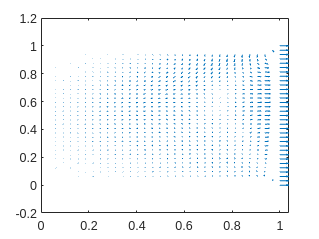

quiver(results.x, results.y, results.u, results.v);

disp(performanceInfo);

    convergence: 1
    nIterations: 4935
       tElapsed: 13.165929999999999



% Verifica se u e v são ou próximos do u e v originais
disp(sum(sum((abs(results.u - u_original)))));

  21.409194863900883



disp(sum(sum((abs(results.v - v_original)))));

   8.102392999536210

